Программа H-поляризация МИУ для цилиндра квадратного сечения

11_11_20

#### Описание: 

Взял за оснвоу программу для круга с ЛСК и использовал ее для расчета квадрата. Вышло лучше чем исходная ПО для квадрата - т.к. ЭПР схогдиться.

Сравнивал с ПО квадрата со старой формулой Д " MIE_circle_success_testFormulsD_test"

Тут использовалась самая новя формула.

close all;
clear variables;

% fE = fopen('Es_save2.dat','W');

Входные параметры

% global N as dx

k = 2*pi; % волновое число, при лямде = 1
as = 1/pi; % ширина ленты
N = 300; % количество точек коллокации
phi_grad = 0; % угол падения волны [град]
dx = as/N; % растояние между центрами цилиндров

Замена переменных

Новые константы

kdx = k*dx;
gamma = 1.781072417990;
kd4 = kdx/4;
% dx2 = dx/2;
delta = dx/2;
kd6 = kdx/6;
    D0 = kdx*(1+(1i*2/pi)*(log(gamma*kd4)-1));
    D1 = kdx*(1+(1i/pi)*(3*log(3*gamma*kd4)-log(gamma*kd4)-2));
    D2 = kdx*(1+(1i*2/pi)*(log(2*gamma*kd4)-1));

Порог

treshold = 1*dx;
% str = sprintf('Будет посчитано %.f матричных элементов через формулу',  fix(treshold/dx));
% disp(str)
% 
% if treshold == dx
%     warning('Порог равен dx, один матричный элемен будет вычислен аналитически')    
% elseif treshold <= dx
%     warning('Порог меньше dx, ни одного матричного элемента не будет вычислено аналитически')    
%     str2 = sprintf('Порог были принят равным dx = %.i',  dx);
%     disp(str2)
%     treshold = dx;
% end

Генерация точек

Расчет кооодинат центров отрезков разбиения

% S = CoordinatesSource()

Тоже самое но без функции

% S = struct('x', {[]}, 'z', {[]});

% генератора координат для первого участка
for n=1:N
    x1(n) = (n-0.5)*dx;
    z1(n) = 0;
    x2(n) = as;
    z2(n) = (n-0.5)*dx;
    x3(n) = (n-0.5)*dx;
    z3(n) = as;
    x4(n) = 0;
    z4(n) = (n-0.5)*dx;  
end

% S(1).x = x1;
% S(1).z = z1;
% S(2).x = x2;
% S(2).z = z2;
% S(3).x = fliplr(x3);
% S(3).z = z3;
% S(4).x = x4;
% S(4).z = fliplr(z4);



tx = [1 0 -1 0];
tz = [0 1 0 -1];
% X = [S(1).x S(2).x S(3).x S(4).x];
% Z = [S(1).z S(2).z S(3).z S(4).z];
X = [x1 x2 fliplr(x3) x4];
Z = [z1 z2 z3 fliplr(z4)];


Расчет касательных к отрезкам разибения

Tz = [repmat(tz(1),1,N) repmat(tz(2),1,N) repmat(tz(3),1,N) repmat(tz(4),1,N)];
Tx = [repmat(tx(1),1,N) repmat(tx(2),1,N) repmat(tx(3),1,N) repmat(tx(4),1,N)];

Посчитаем n для каждого отрезка

%   нормальный вектор найдем с помощью матрицы повороты
    a = -90;
    matrix = [cosd(a),-sind(a); sind(a),cosd(a)];

for i = 1 : 4*N
     matrix_temp = [Tx(i), Tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

Изучим один цикл

Es = zeros(4*N,4*N);

for m = 1 : 4*N
%   Координаты в исходной системе координат (в ГСК) 
% - т.к. точки находятся в центре отрезков разбиения
    xm = X(m);
    zm = Z(m);
    txm = Tx(m);
    tzm = Tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
%     leter = strcat('m =_', int2str(m), ' из_', int2str(4*N));
%     disp(leter);
    
    for n = 1 : 4*N
    %   Координаты в исходной системе координат (в ГСК)
        xn = X(n);
        zn = Z(n);
        txn = Tx(n);
        tzn = Tz(n);
        nxn = nx(n);
        nzn = nz(n);

    %   Центр новой системы кооридны - середина отрезка (в ГСК)

Давай возьмем середину отрезка

        x_begin_O2 = xn;
        z_begin_O2 = zn;
        
    %   Растояние между началом координат О2 и точкой наблюдений (в ГСК)
        x_mO2 = xm - x_begin_O2;
        z_mO2 =  zm - z_begin_O2;
         
%       Положим этот вектор на новую СК
%       Координаты этой точки (в ЛСК)
        xmO2 = x_mO2*txn + z_mO2*tzn;
        zmO2 = x_mO2*nxn + z_mO2*nzn;
        
    %   Растояние от n до точки m (в ЛСК)  

Т.к. взяли на начало середину отрезка то тут будет

        xmnO2 = xmO2;
        zmnO2 = zmO2; 

%       Растояние между m и n (в ГСК)
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
%         r_test = sqrt(xmnO2^2 + zmnO2^2);
        
%       Расчет матричных элементов (в ЛСК)  
        if r < 0.001*dx
            Zm = D0;
   
        elseif r <= dx 
%             k_xm_plus = k*(abs(xmnO2)+delta);
%             k_xm_minus = k*(abs(xmnO2)-delta);
%             Zm = kdx +(1i*2/pi)*( k_xm_plus*log(gamma*k_xm_plus/2)-k_xm_minus*log(gamma*k_xm_minus/2)-kdx );
%             
            xmn_plus_delta = (xmnO2) + delta;
            xmn_minus_delta = (xmnO2) - delta;
            r_plus_delta = sqrt(xmn_plus_delta^2 + zmnO2^2);
            r_minus_delta = sqrt(xmn_minus_delta^2 + zmnO2^2);
%             zmn = abs(zmnO2);
%             Zm = kdx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(asin(xmn_plus_delta/r_plus_delta)- asin(xmn_minus_delta/r_minus_delta)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx);
            zmn = zmnO2;
            Zm = kdx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(atan(xmn_plus_delta/zmn)- atan(xmn_minus_delta/zmn)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx);

        else
            f2 = besselh(0,1,k*r);
            Zm = k*dx*f2;
        end
        
        r_x_plus = sqrt((xmnO2+delta)^2+zmnO2^2);
        r_x_minus = sqrt((xmnO2-delta)^2+zmnO2^2);
        
        Esx= (xmnO2-delta)/r_x_minus*besselh(1, 1, k*r_x_minus) - (xmnO2+delta)/r_x_plus*besselh(1, 1, k*r_x_plus) + Zm;
        Esz = (zmnO2)/r_x_minus*besselh(1, 1, k*r_x_minus) - (zmnO2)/r_x_plus*besselh(1, 1, k*r_x_plus);        

         tx_betven_vectors = txm*txn + tzm*tzn;
        tz_betven_vectors = txm*nxn + tzm*nzn;
        
        Es(m,n) = Esx*tx_betven_vectors + Esz*tz_betven_vectors;
            
%       запись в файл для сохранения
    end 
%     current_m = m;    
%     current_n = n;
%         if current_n == 4*N
%             fprintf(fE, '%10.5f ', current_m);
%             for i= 1 : 4*N                
%                 fprintf(fE, ' %10.5f %10.5f ', real(Es(current_m,i)), imag(Es(current_m,i)));                
%             end
%             fprintf(fE, '\n');
%        	end   
end

% fclose(fE);

Расчет падающего поля

for m=1:4*N
    cx = -1i*k*cosd(phi_grad);
    cz = -1i*k*sind(phi_grad);
    % Определим координаты
    xm = X(m);
    zm = Z(m);
    txm = Tx(m);
    tzm = Tz(m);
    
%   Итоговое падающее поел - это суперпозиция полей
    Eix = +4*1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
    Eiz = -4*1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
    Ei(m,1) = Eix*txm + Eiz*tzm; 
end

Посчитаем токи и построим график

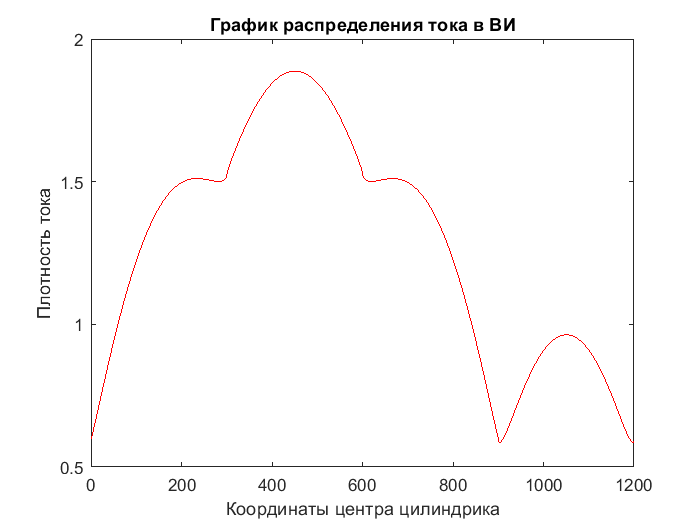

% расчеток токов ВИ 
I=Es\Ei;
       
% номера ВИ для графика 
n_for_graf = zeros(1, 4*N);
for i = 1 : 4*N
     n_for_graf(i) = i;
end

% построение графика респределения токов в ВИ

figure;
plot(n_for_graf, abs(I), 'r');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
ylabel('Плотность тока');

Запись в файл токов

f01 = fopen('I_MIE_sqr_by_circle_1pi_pres.dat','w');

for n=1:4*N
%     Inorm = abs(I/120/pi*1000);
    fprintf(f01,' %10.5f %10.5f\n', (n_for_graf(n)*dx-dx/2)/(4*as), abs(I(n))/max(abs(I)));
end

fclose(f01);

## ЭПР

for p = 1 : 721
    Sum_H = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k*cosd(phi);
    cz = - 1i*k*sind(phi);
    

        for n = 1 : 4*N
            txn = Tx(n);
            tzn = Tz(n);
            xn = X(n);
            zn = Z(n);
            
            Sum_H = Sum_H + 1/4*I(n)*k*dx*(txn*sind(phi) - tzn*cosd(phi))*exp(cx*xn+cz*zn);
        end
    
RCS(p) = 10*log10((2/pi)*Sum_H*conj(Sum_H));

end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA ,RCS,'r-');

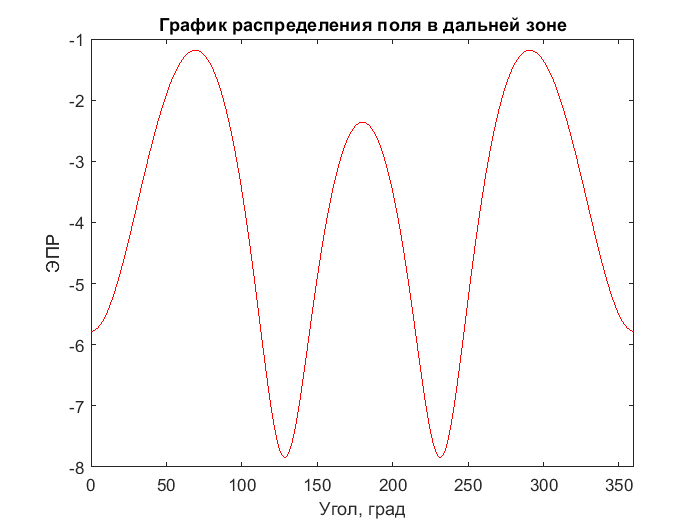

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

Запись в файл ЭПР

f02 = fopen('DA_MIE_sqr_by_circle_1pi_pres.dat','w');
for p = 1 : 721
    fprintf(f02, ' %10.5f %10.5f\n', phi_for_graf_DA(p), RCS(p));
end
fclose(f02);

